load VORTALL.mat VORTALL
P=90;
p=cast(P/100*size(VORTALL,1),"uint32");
trainx=VORTALL(1:p,:)';
testx=VORTALL(p+1:size(VORTALL,1),:)';
trainx=normalize(trainx,'range',[0 1]);
testx=normalize(testx,'range',[0 1]);

X_train=trainx(:,1:size(trainx,2)-1);
Y_train=trainx(:,2:size(trainx,2));
X_test=testx(:,1:size(testx,2)-1);
Y_test=testx(:,2:size(testx,2));

net=patternnet(10,'trainscg','mse');

net=train(net,X_train,Y_train);

view(net)
y=net(X_train);
y2=net(X_test);

perf_train=perform(net,X_train,Y_train);
perf_test=perform(net,X_test,Y_test);

perf=zeros(8,1);
perf(8)=perf_test;

for P=80:-10:20
    p=cast(P/100*size(VORTALL,1),"uint32");
    trainx=VORTALL(1:p,:)';
    testx=VORTALL(p+1:size(VORTALL,1),:)';
    trainx=normalize(trainx,'range',[0 1]);
    testx=normalize(testx,'range',[0 1]);
    
    X_train=trainx(:,1:size(trainx,2)-1);
    Y_train=trainx(:,2:size(trainx,2));
    X_test=testx(:,1:size(testx,2)-1);
    Y_test=testx(:,2:size(testx,2));
    
    net=patternnet(10,'trainscg','mse');
    net=train(net,X_train,Y_train);
    pause(5);

    perf_train=perform(net,X_train,Y_train)
    perf(P/10-1)=perform(net,X_test,Y_test);
end

perf_train = 0.0032

perf_train = 0.0033

perf_train = 0.0035

perf_train = 0.0036

perf_train = 0.0039

perf_train = 0.0046

perf_train = 0.0056

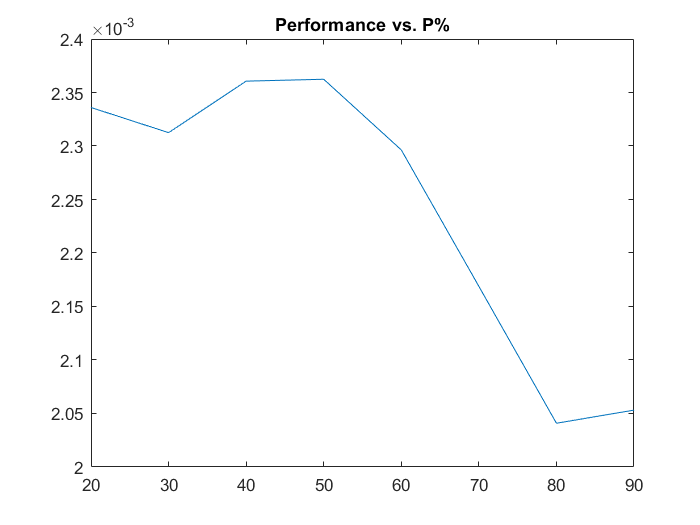

plot(20:10:90,perf);
title('Performance vs. P%')